# Antenna Frequency Response Report Generator

## 1 Configuration

clear;
close all;
clc;
clf;
sympref('FloatingPointOutput',false);
sympref('AbbreviateOutput',true);
format LongEng;

cmdStyles="ieee";
%cmdColorOrder = [0 0 1; 1 0 0; 0 0 0 ];           % https://jp.mathworks.com/help/matlab/creating_plots/defining-the-color-of-lines-for-plotting.html

dir_output = "../inout_sps";
savefile_types = [".png"; ".fig"; ".emf";];                     % .csv has a matrix bug.

% filenames_toload = ["VMTM_Mono_L10_sub72x57_S2.s1p";"VMTM_Mono_L10_sub30x40.s1p";"PCB BW 3cell C-freq 0.6pf Best modal Ground_env01_ESR_roughness - Setup1_Sweep_10GHz.s1p";];
% alternate_filenames = ["Proposed antenna #4-1";"Proposed antenna #4-2";"Previous work"];
% cmdXlim_GHz = [1;12];
% cmdLineStyleOrder = ["-" "-" "--"];
% cmdLineWidthOrder = [2; 2; 1];

filenames_toload    = ["VMTM_sim_Dipole_20221231_L10_LowHeight_v6.5_asym - Setup1_Sweep.s1p"; "VMTM_sim_Dipole_20221231_L10_LowHeight_v6.5.s1p";];
alternate_filenames = ["Proposed antenna #5-1";      "Mirroring structure";];
cmdXlim_GHz = [1;10];
smith1_range = [3.16; 8.15];
smith2_range = [3.16; 8.15];

cmdColorOrder = [0 0 1; 0.4660 0.6740 0.1880; 1 0 0];           % https://jp.mathworks.com/help/matlab/creating_plots/defining-the-color-of-lines-for-plotting.html
cmdLineStyleOrder = ["-" "-" "--"];
cmdLineWidthOrder = [2; 1; 1];

## 2 Return Loss [dB]

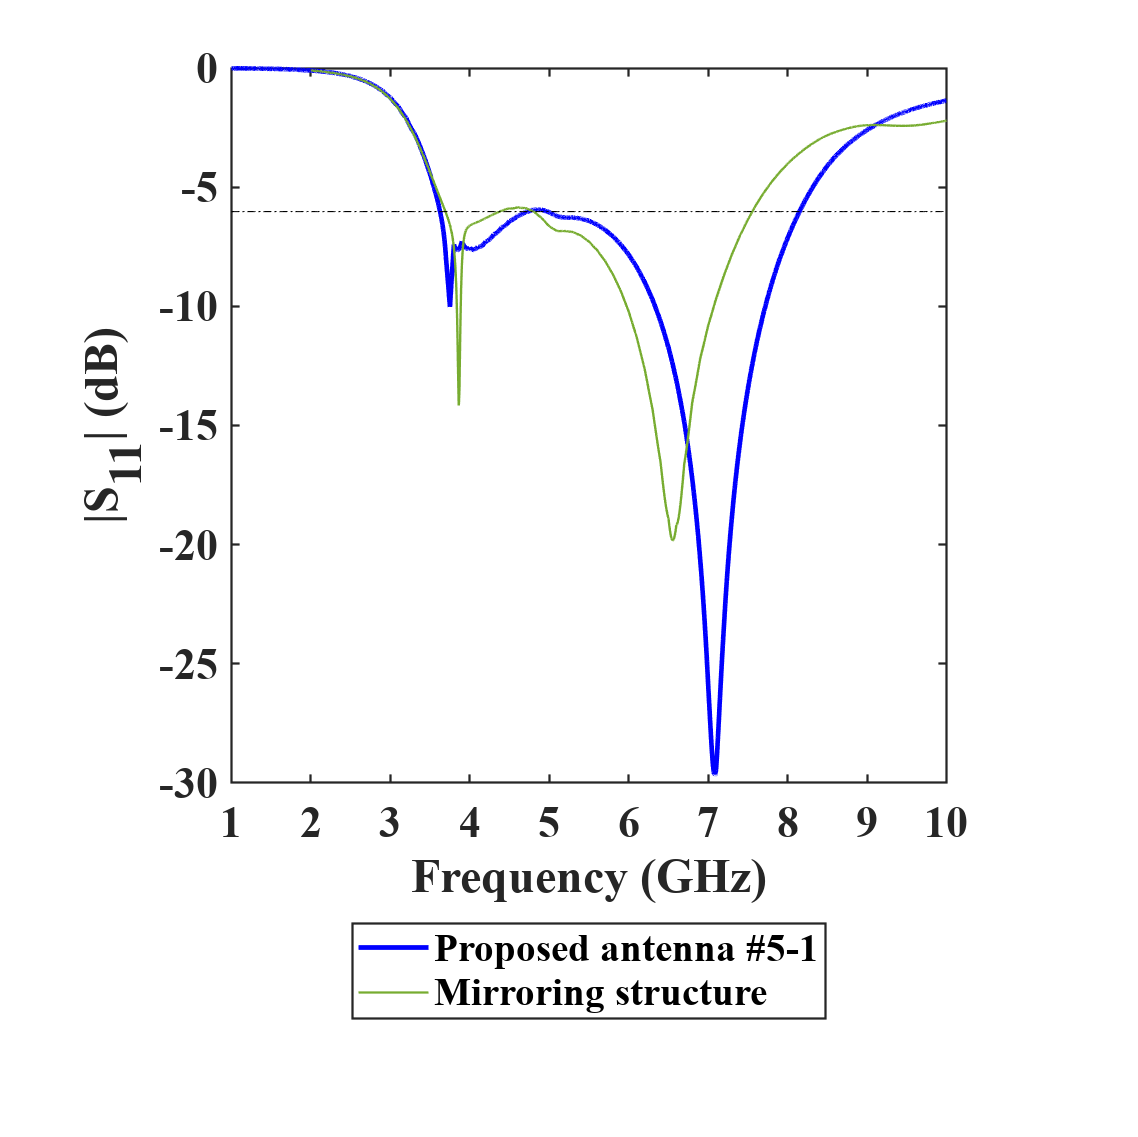

cmd_genfig_s11_logmag(dir_output, filenames_toload, cmdXlim_GHz, cmdStyles, savefile_types, alternate_filenames, cmdColorOrder, cmdLineStyleOrder, cmdLineWidthOrder,"vswr3");

## 3 VSWR

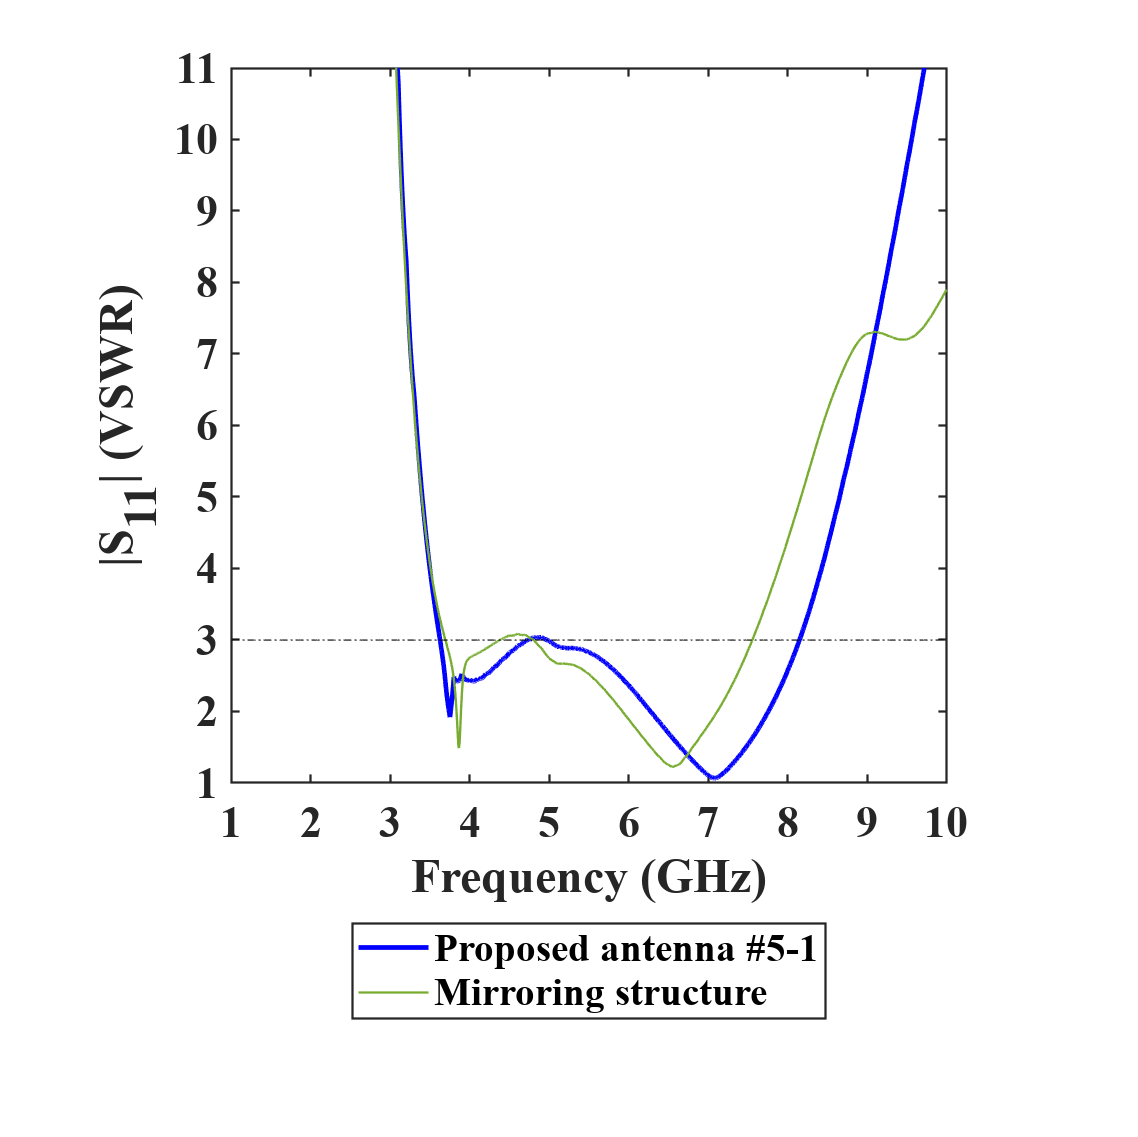

cmd_genfig_s11_vswr(dir_output, filenames_toload, cmdXlim_GHz, cmdStyles, savefile_types, alternate_filenames, cmdColorOrder, cmdLineStyleOrder, cmdLineWidthOrder, "vswr3");

## 4 Z Parameters

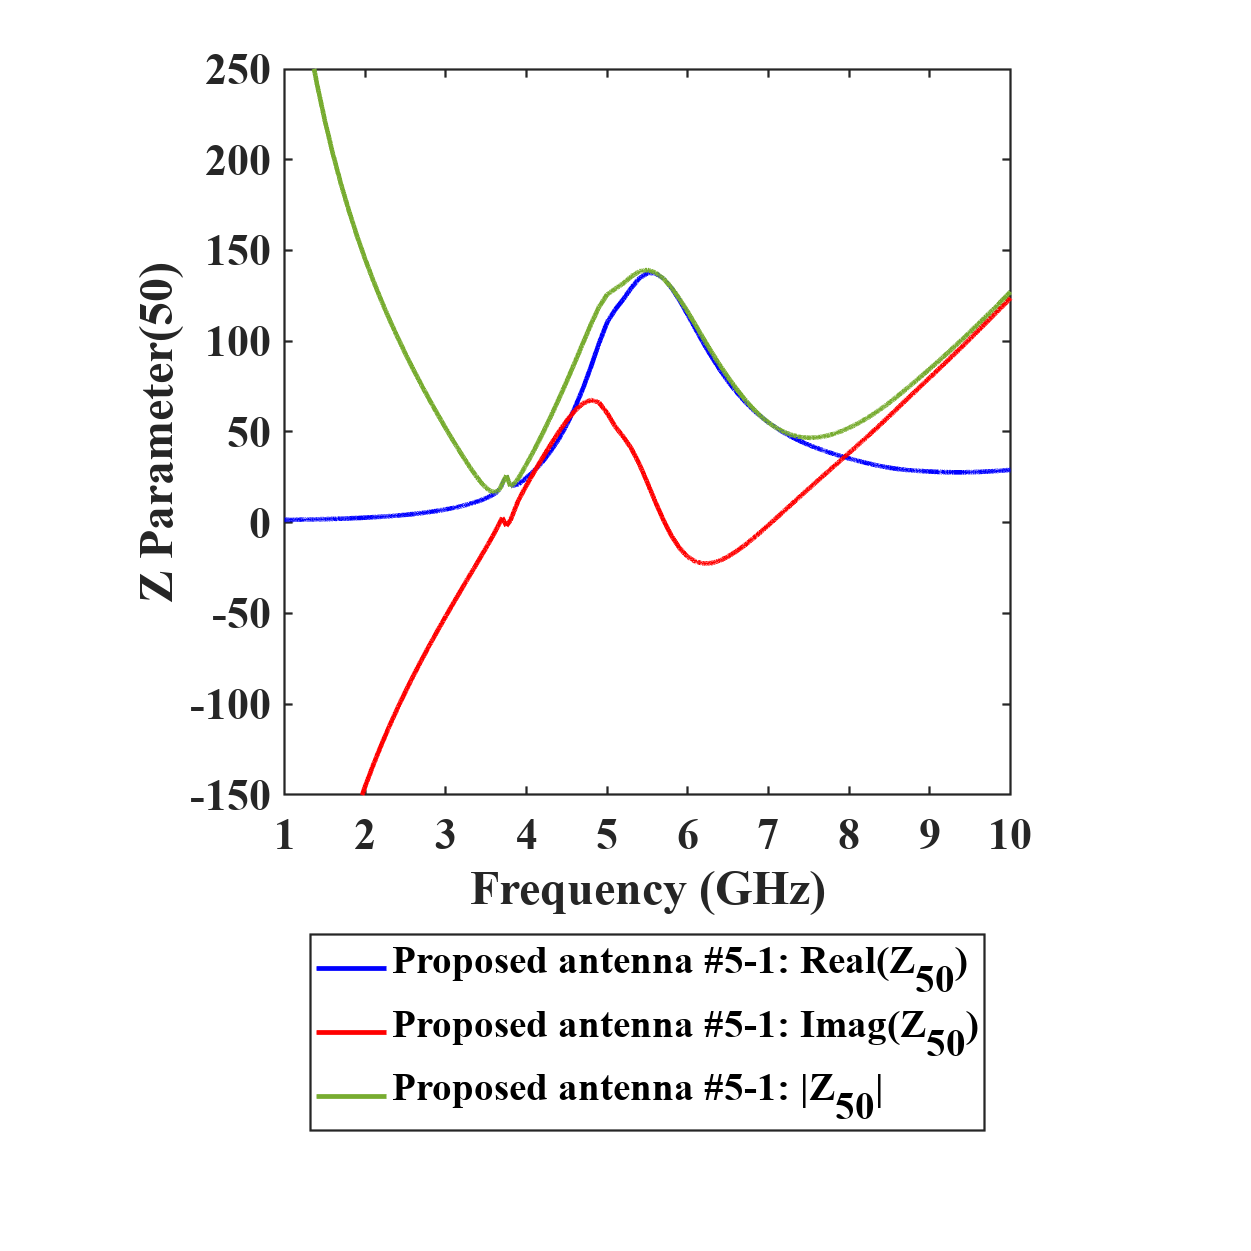

cmd_genfig_s11_zparam(dir_output, filenames_toload(1), alternate_filenames(1), cmdXlim_GHz, cmdStyles, savefile_types, [0 0 1; 1 0 0; 0.4660 0.6740 0.1880], cmdLineStyleOrder, cmdLineWidthOrder);

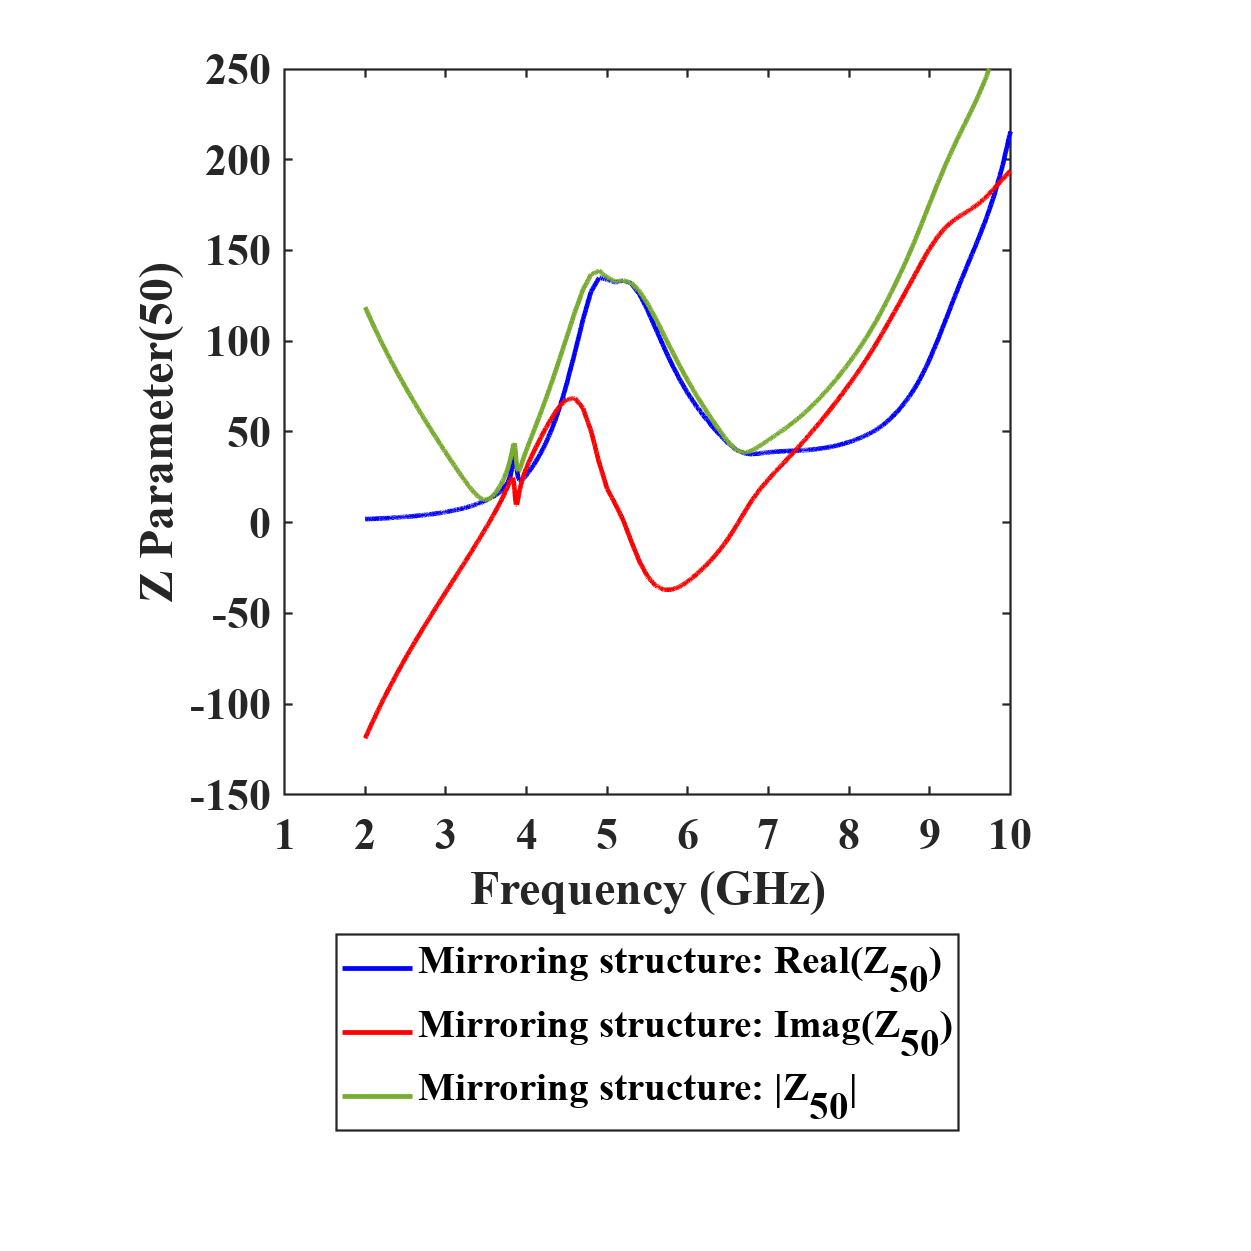

cmd_genfig_s11_zparam(dir_output, filenames_toload(2), alternate_filenames(2), cmdXlim_GHz, cmdStyles, savefile_types, [0 0 1; 1 0 0; 0.4660 0.6740 0.1880], cmdLineStyleOrder, cmdLineWidthOrder);

## 5 S11 Smith Chart (full-range)

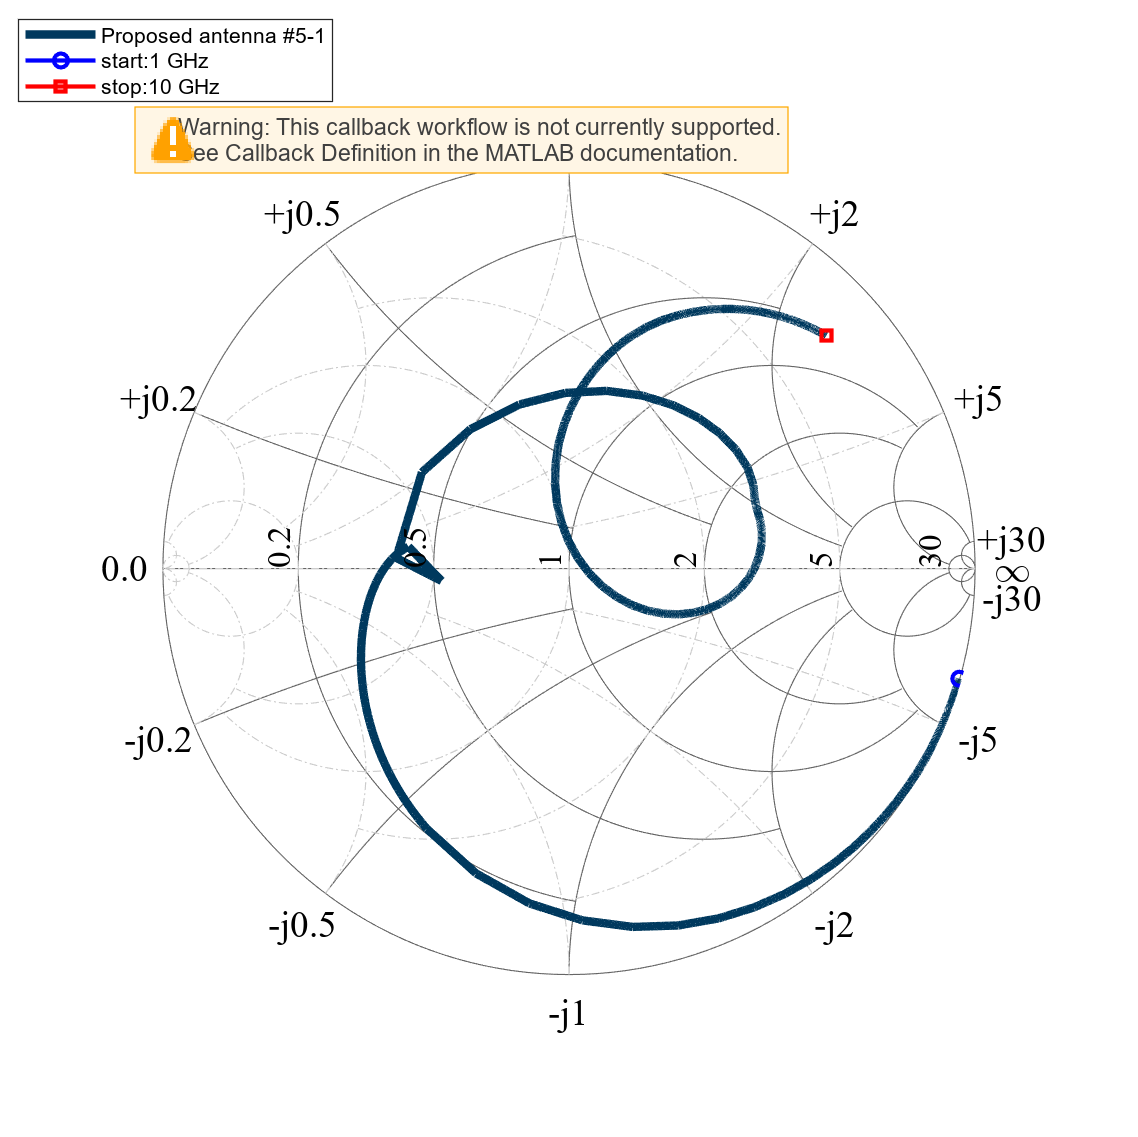

cmd_genfig_s11_smith(dir_output, filenames_toload(1), alternate_filenames(1), "auto", cmdXlim_GHz, cmdStyles, savefile_types, cmdColorOrder, {'-','-','-'}, cmdLineWidthOrder);

## 6 S11 Smith Chart (reduced-range)

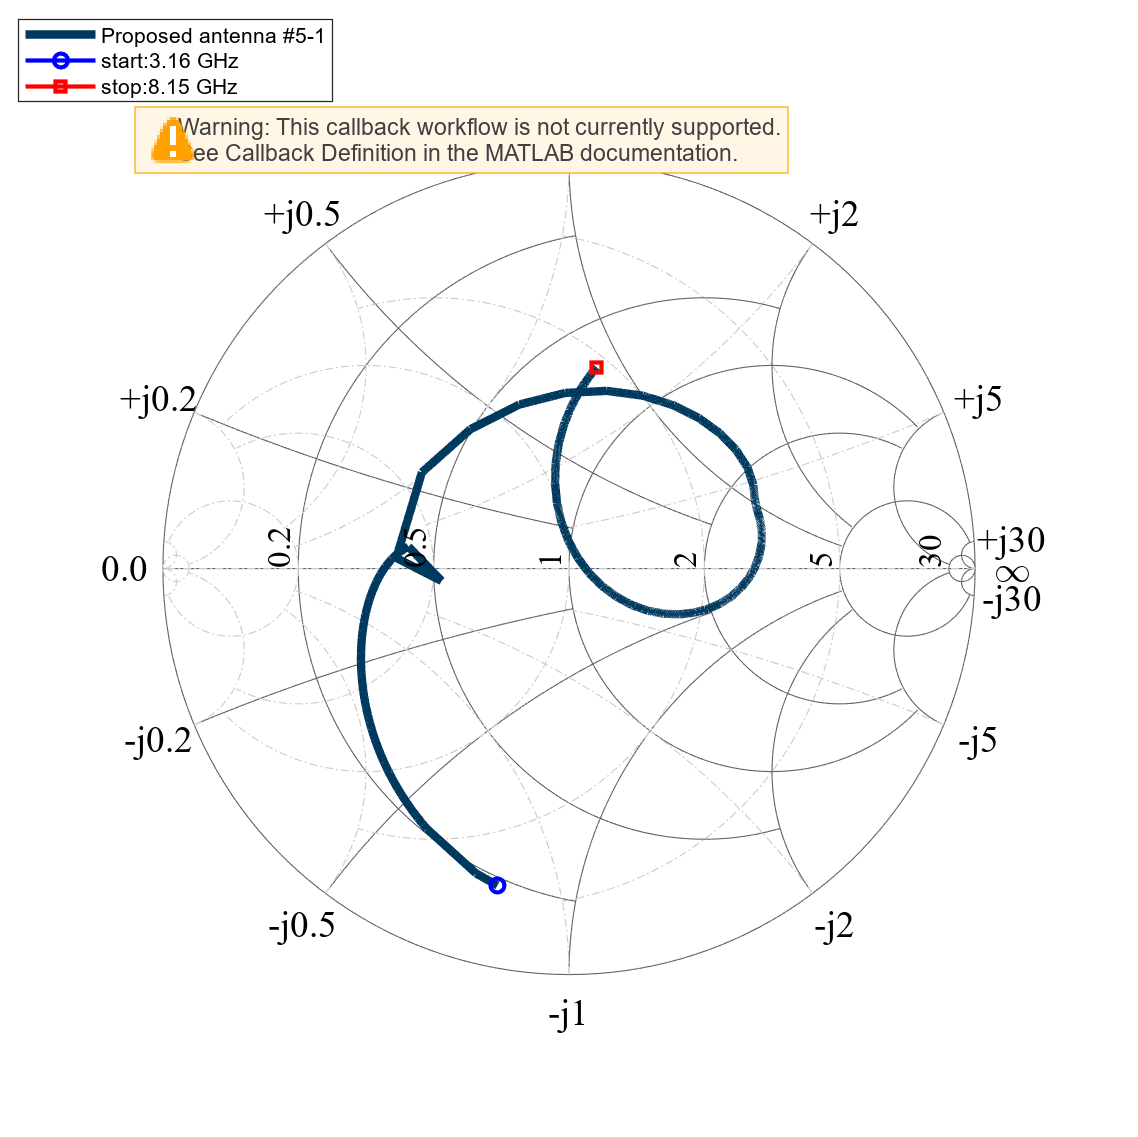

cmd_genfig_s11_smith(dir_output, filenames_toload(1), alternate_filenames(1), "man", smith1_range, cmdStyles, savefile_types, cmdColorOrder, {'-','-','-'}, cmdLineWidthOrder);

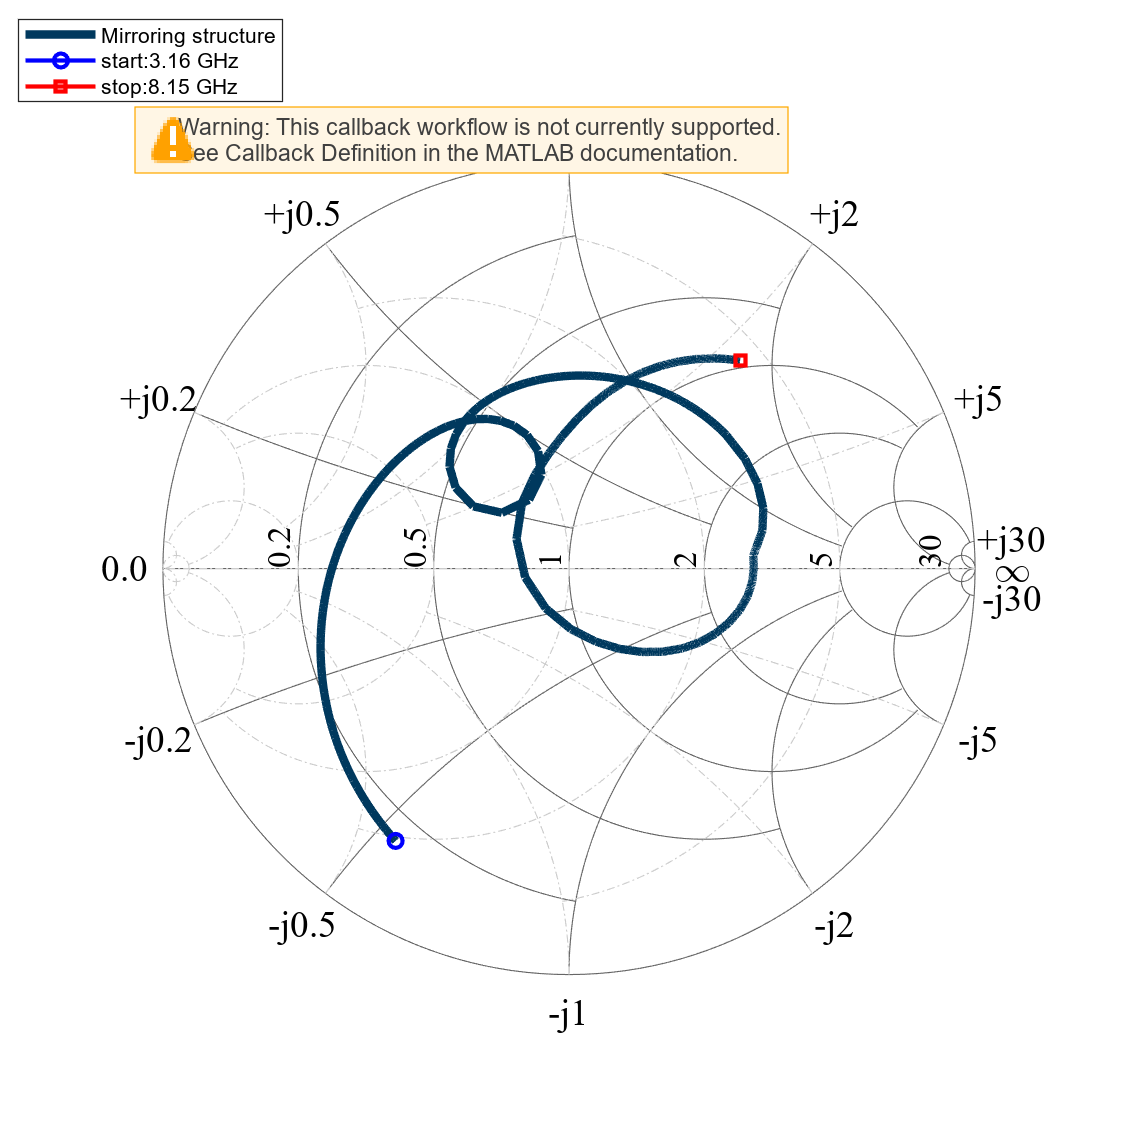

cmd_genfig_s11_smith(dir_output, filenames_toload(2), alternate_filenames(2), "man", smith1_range, cmdStyles, savefile_types, cmdColorOrder, {'-','-','-'}, cmdLineWidthOrder);

% error: creating .csv file.. cmd_genfig_s11_smith(dir_output, filenames(1), "man", [1.5;2.5], cmdStyles, [".csv";".png"], cmdColorOrder, {'-','-','-'}, cmdLineWidthOrder);

## 7 S11 Phase (unwrapped)

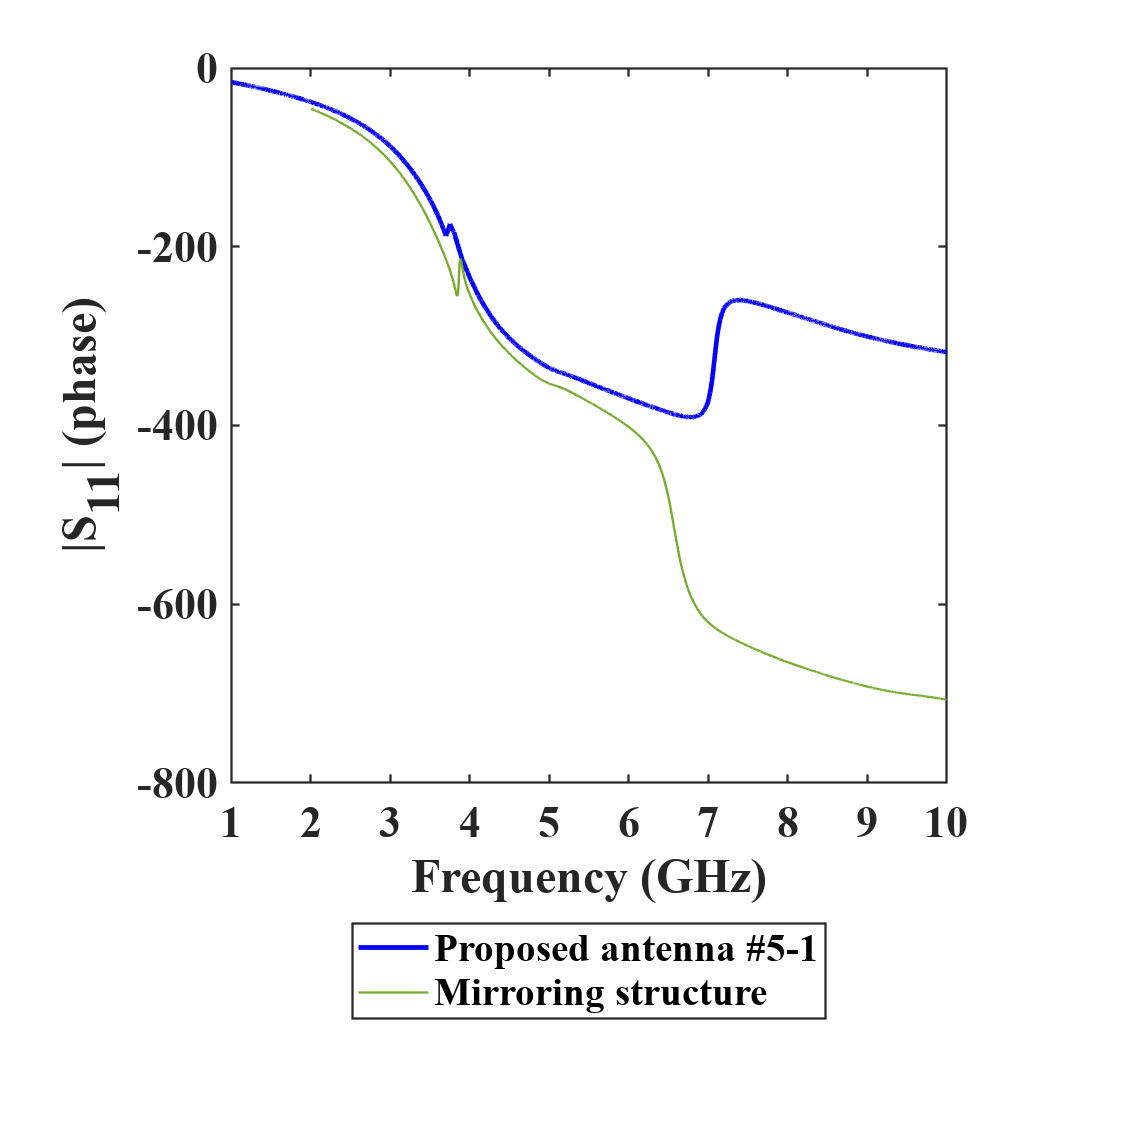

cmd_genfig_s11_phase(dir_output, filenames_toload, cmdXlim_GHz, cmdStyles, savefile_types, alternate_filenames, cmdColorOrder, cmdLineStyleOrder, cmdLineWidthOrder,1);

## 8 S11 Phase (wrapped)

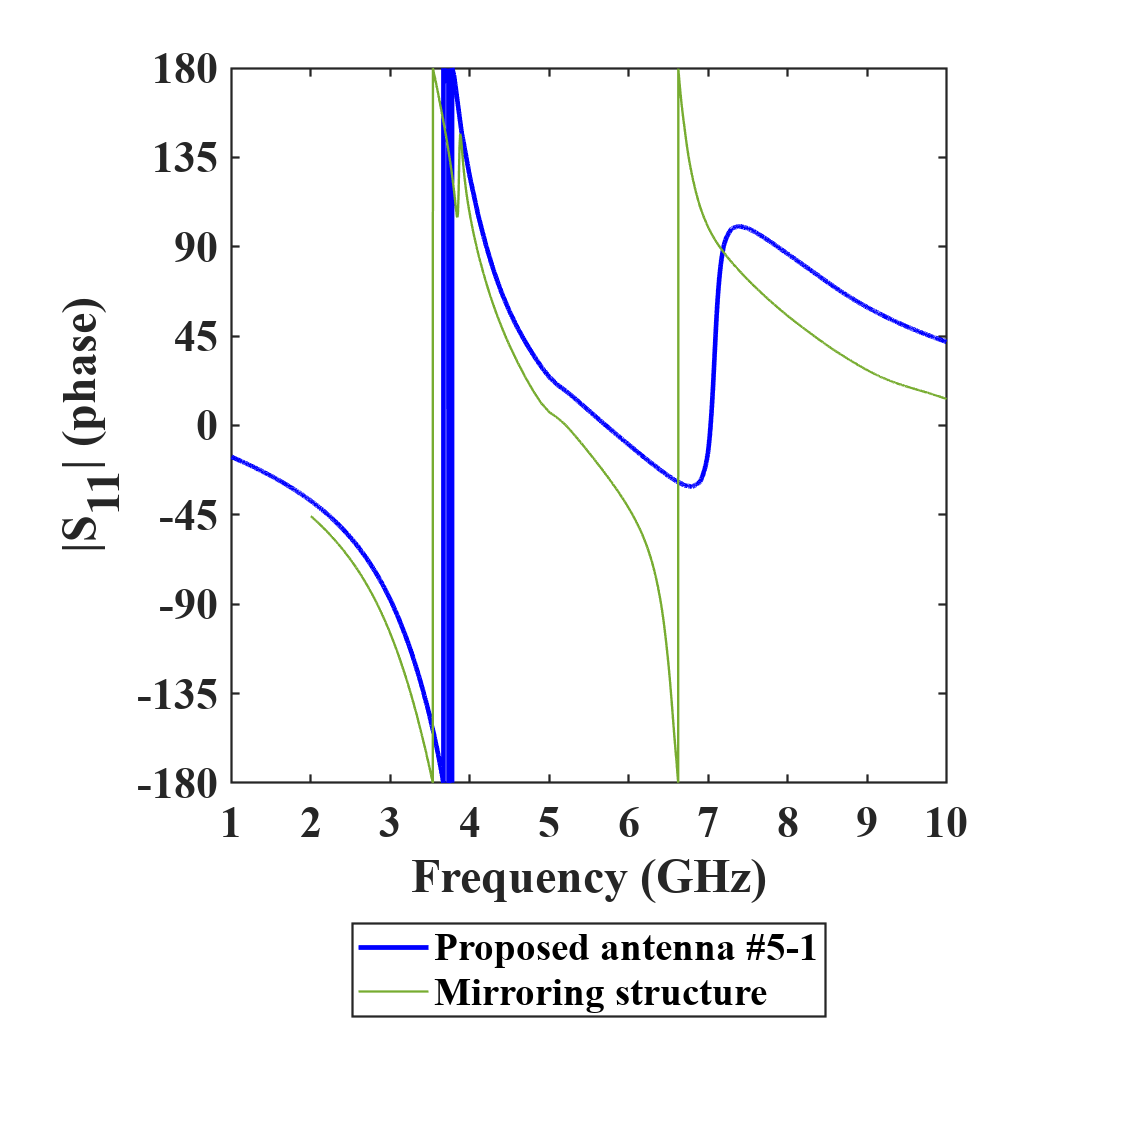

cmd_genfig_s11_phase(dir_output, filenames_toload, cmdXlim_GHz, cmdStyles, savefile_types, alternate_filenames, cmdColorOrder, cmdLineStyleOrder, cmdLineWidthOrder,0);